# Resolve Tiny Tone

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/psdsig.mat
n = length(t);
y1 = sin(2*pi*fr*t);
y2 = 0.01*sin(2*pi*3*fr*t);
y3 = 2*sin(2*pi*4*fr*t);
sig = 1e-3*(y1+y2+y3);

## Task 1

In this task, you should change the window until all 3 peaks are found correctly. You want to minimize the distance, or the error, between the peak's triangle marker and the pink vertical lines.

beta = 10;
[p, f] = periodogram(sig, kaiser(n, beta), 2^12, fs);

This code plots the spectrum. The peaks visualized with triangle markers. The correct tone locations are visualized with vertical dashed lines.

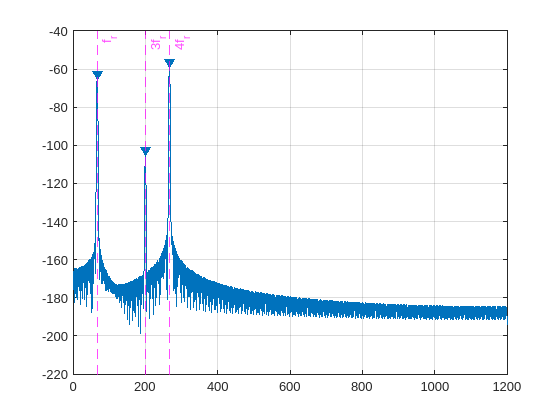

figure;
findpeaks(10*log10(p), f, "NPeaks", 3, "SortStr", "descend");
xline(fr, "m--", "f_r")
xline(3*fr, "m--", "3f_r")
xline(4*fr, "m--", "4f_r")